% ejemplo de diseño de filtro digital
% filipuzzi, fernando rafael
% fecha: 20230313
% matlab2022b

close all; clear all; clc;
digits(300);
addpath ./embedded
addpath ./mifiltertools
addpath ./utils
format LONGE

**Filtro - FIR - Diseño del filtro**

**Parámetros de diseño**

fm=22418;             % Hz,  Frecuencia de Muestreo
f1=1000 ; f2=1500;          
N=15 ;   
TIPO_FILTRO  ="pasa_alto"; TIPO="stm32";
TIPO_VENTANA ="hamming";

**Diseño del filtro**

- Normalización de la frecuencia

Wn=[f1/(fm/2) f2/(fm/2)];%normaliza con la mitad de la frecuencia de muestreo

- Diseño del filtro con la función de matlab para constrastar

filtroSelected='low';
file_wsp='wsp/fir.map';
Fc=Wn(end);
switch TIPO_FILTRO
    case "pasa_bajo"
      filtroSelected='low';
    case "pasa_alto"
      filtroSelected='high'; 
    case "pasa_banda"
      filtroSelected='bandpass'; 
      Fc=Wn;
    case "rechaza_banda"
      filtroSelected='stop'; 
      Fc=Wn;
end
Az = 1;
Bz = fir1(N-1, Fc, filtroSelected, 'noscale');
length(Bz)

ans =     15


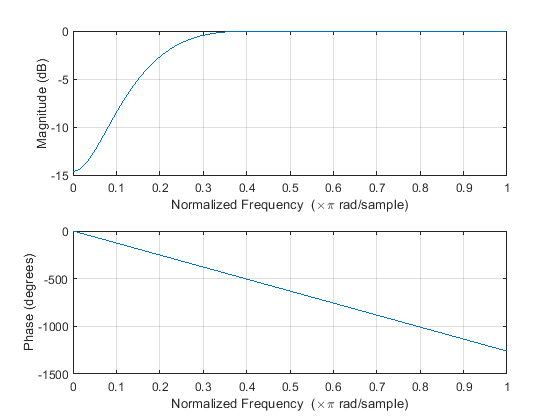


fig1=figure; freqz(Bz,Az,2048); grid on;
saveas(fig1,strcat('output/',TIPO,'_fir_',TIPO_FILTRO,'_matlab_1'),'jpg');

- Diseño del filtro realizado.

[Bz,Az]=mi_fir1(N, Wn*2, TIPO_FILTRO, TIPO_VENTANA);
length(Bz)

ans =     15


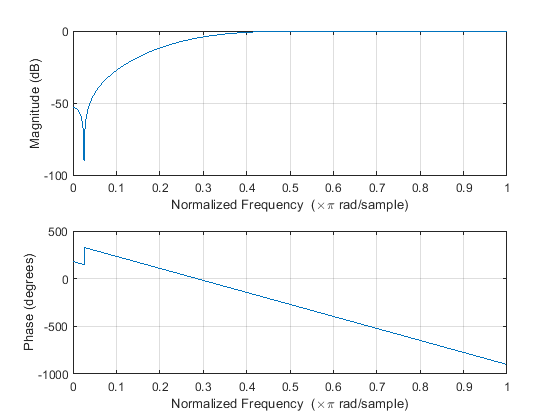

fig2=figure; freqz(Bz, Az, 2048); grid on;
saveas(fig2,strcat('output/',TIPO,'_fir_',TIPO_FILTRO,'_2'),'jpg');

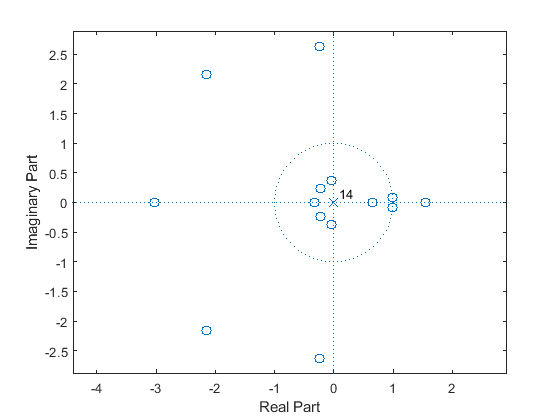

fig3=figure; zplane( [Bz zeros(1, N- length(Bz)+1) ], [Az zeros(1, N- length(Az)+1) ] );
saveas(fig3,strcat('output/',TIPO,'_fir_',TIPO_FILTRO,'_3'),'jpg');

syms z; ecu_latex = ['H(z)=', latex(poly2sym(Bz,z))];
save_ecu(strcat('output/', TIPO, '_fir_', TIPO_FILTRO,'_ecu_z.txt'), ecu_latex);

**Generación de la linea de código para el micrcontrolador - **vector de coeficientes

if(TIPO=="stm32")
    PRECISION_STM32=8;
    stm32_coef=to_stm32(Bz, Az, N, fm, PRECISION_STM32, strcat('FIR - ', TIPO_FILTRO))
    saveImplementacion(strcat('output/', TIPO, '_fir_', TIPO_FILTRO,'_coef.txt'), stm32_coef);
    fprintf('%s\n',stm32_coef)
end    

stm32_coef =     '//Filtro FIR -pasa_alto -  
     //Orden: 15
     //Frecuencia de Muestreo: 22418 (Hz)
     #define ORDEN 14
     double coef_x[]= {0.00140802,0.00629594,0.01408120,0.00765779,-0.03955279, 
     			-0.13078253,-0.22639634,0.73235793,-0.22639634,-0.13078253, 
     			-0.03955279,0.00765779,0.01408120,0.00629594,0.00140802 
     			};
     double coef_y[]= {-1.00000000,0.00000000,0.00000000,0.00000000,0.00000000, 
     			0.00000000,0.00000000,0.00000000,0.00000000,0.00000000, 
     			0.00000000,0.00000000,0.00000000,0.00000000,0.00000000 
     			};'


//Filtro FIR -pasa_alto -  
//Orden: 15
//Frecuencia de Muestreo: 22418 (Hz)
#define ORDEN 14
double coef_x[]= {0.00140802,0.00629594,0.01408120,0.00765779,-0.03955279, 
			-0.13078253,-0.22639634,0.73235793,-0.22639634,-0.13078253, 
			-0.03955279,0.00765779,0.01408120,0.00629594,0.00140802 
			};
double coef_y[]= {-1.00000000,0.00000000,0.00000000,0.00000000,0.00000000, 
			0.00000000,0.00000000,0.00000000,0.00000000,0.00000000, 
			0.00000000,0.00000000,0.00000000,0.00000000,0.00000000 
			};


**Generación de los coecientes para la fpga**

if(TIPO=="fpga")
    Nbits=64;
    Qbits=32;      
    fpga_coef=to_fpga(Bz, Az, N, fm, Qbits,Nbits, strcat('FIR - ', TIPO_FILTRO));
    saveImplementacion(strcat('output/', TIPO, '_fir_', TIPO_FILTRO,'_coef.txt'), fpga_coef);
    fprintf('%s\n',fpga_coef) 
end

**Generación de la linea para inicializar el callback de simulink**

simulink_coef=to_simulink(Bz, Az, N, fm, PRECISION_STM32, strcat('FIR - ' , TIPO_FILTRO));
saveImplementacion(strcat('output/', TIPO, '_fir_', TIPO_FILTRO,'_simulink_coef.txt'), simulink_coef); 
fprintf('%s\n',simulink_coef) 

	%Filtro FIR -pasa_alto -  
	%Orden: 15
	%Frecuencia de Muestreo: 22418 (Hz)
	Fm=22418;
	ORDEN=15;
	coef_x= [0.0014080165,0.0062959449,0.014081196,0.0076577925,-0.039552785, ...
			-0.13078253,-0.22639634,0.73235793,-0.22639634,-0.13078253, ...
			-0.039552785,0.0076577925,0.014081196,0.0062959449,0.0014080165, ...
			];
	coef_y= [-1,];



save(strcat('output/', TIPO,'_fir_',TIPO_FILTRO,'_coef.mat' ));